# VE444 HW3 Name: Fang Baole ID: 518370910056

1. Consider the SIR-model from class, with permanent immunity and recovery rate δ= 0.1.

Plot a simulation of the infection process (S,I, R denoted as the fraction of people in each group) in a population of 1000 people, and the transmission rate of 0.2. The initial recovery group size is 0, and the initial infected group size is 1. (Hint: You might want to use first-order differential equation solver in your language. Or just calculate the size in an iterative way)

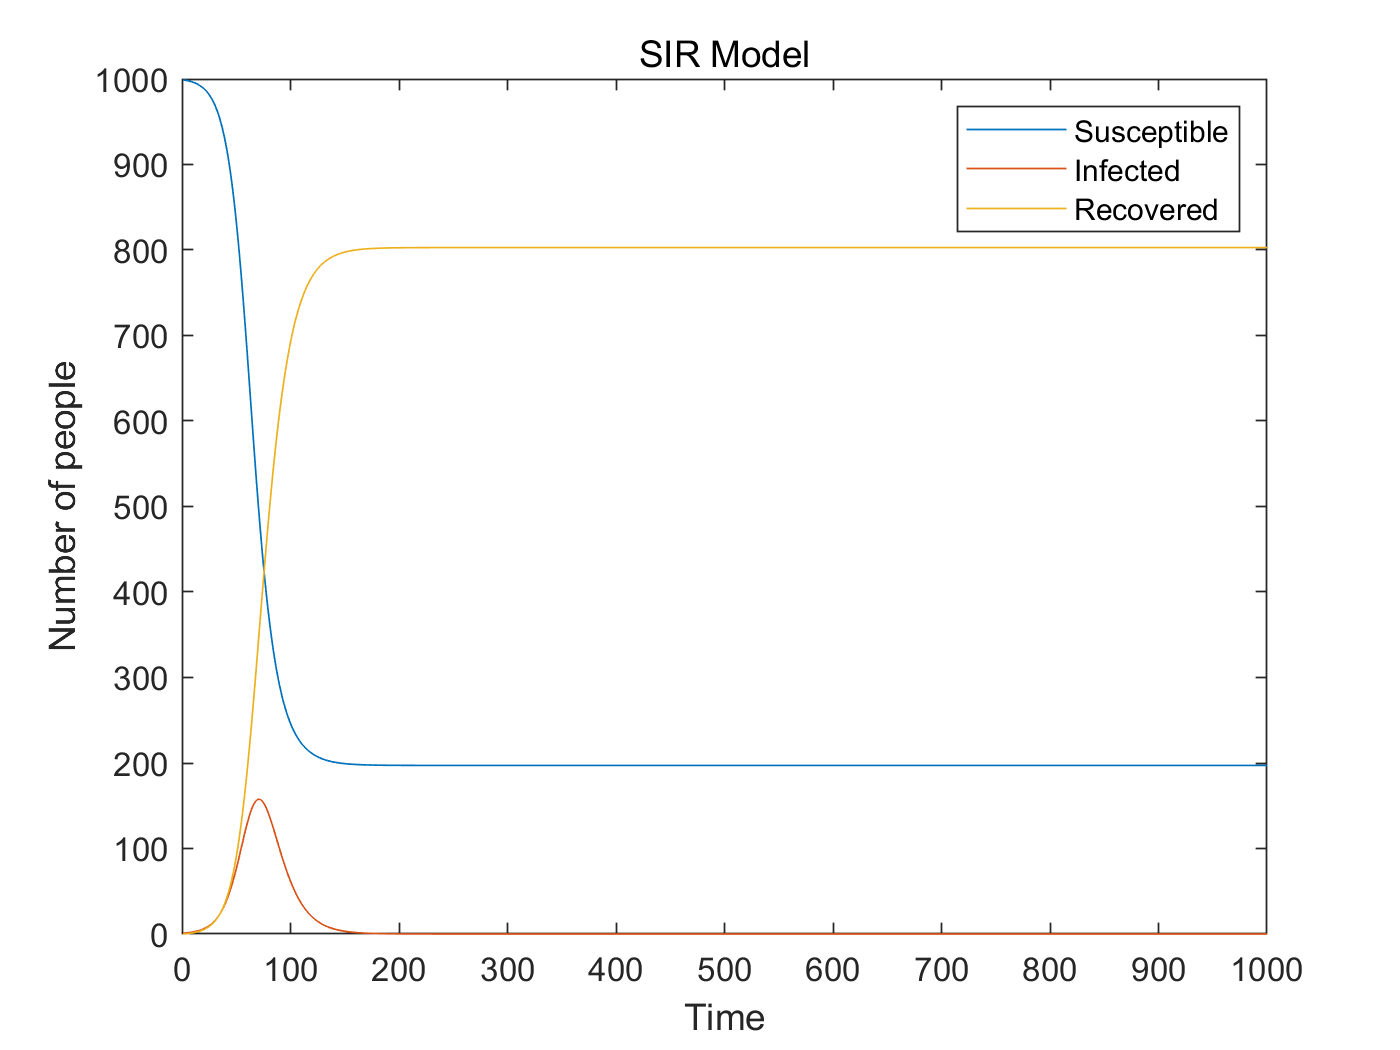

clear
clc

delta=0.1;
beta=0.2;
N=1000;
R=[0];
I=[1];
S=[999];
i=1;

for i=1:999
    dS=-beta*S(i)*I(i)/N;
    dR=delta*I(i);
    dI=beta*S(i)*I(i)/N-delta*I(i);
    S(i+1)=S(i)+dS;
    R(i+1)=R(i)+dR;
    I(i+1)=I(i)+dI;
end

x=[1:1000];
plot(x,S,x,I,x,R);
title("SIR Model");
xlabel("Time");
ylabel("Number of people");
legend("Susceptible", "Infected", "Recovered");

2. Suppose we have eight employees at a small company, where their relationship score can be measured as values between -100 to +100. A value of zero means the two employees haven’t interacted or are indifferent (Recorded in Employee_Relationships.txt). Each employee is further asked to choose 3 movies that they would most enjoy watching for the upcoming company movie night (Recorded in Employee_Movie_Choices.txt).

2.1 Build a friend (with friendship value greater than zero) network, and write a program to plot the degree distribution graph of this friend graph.

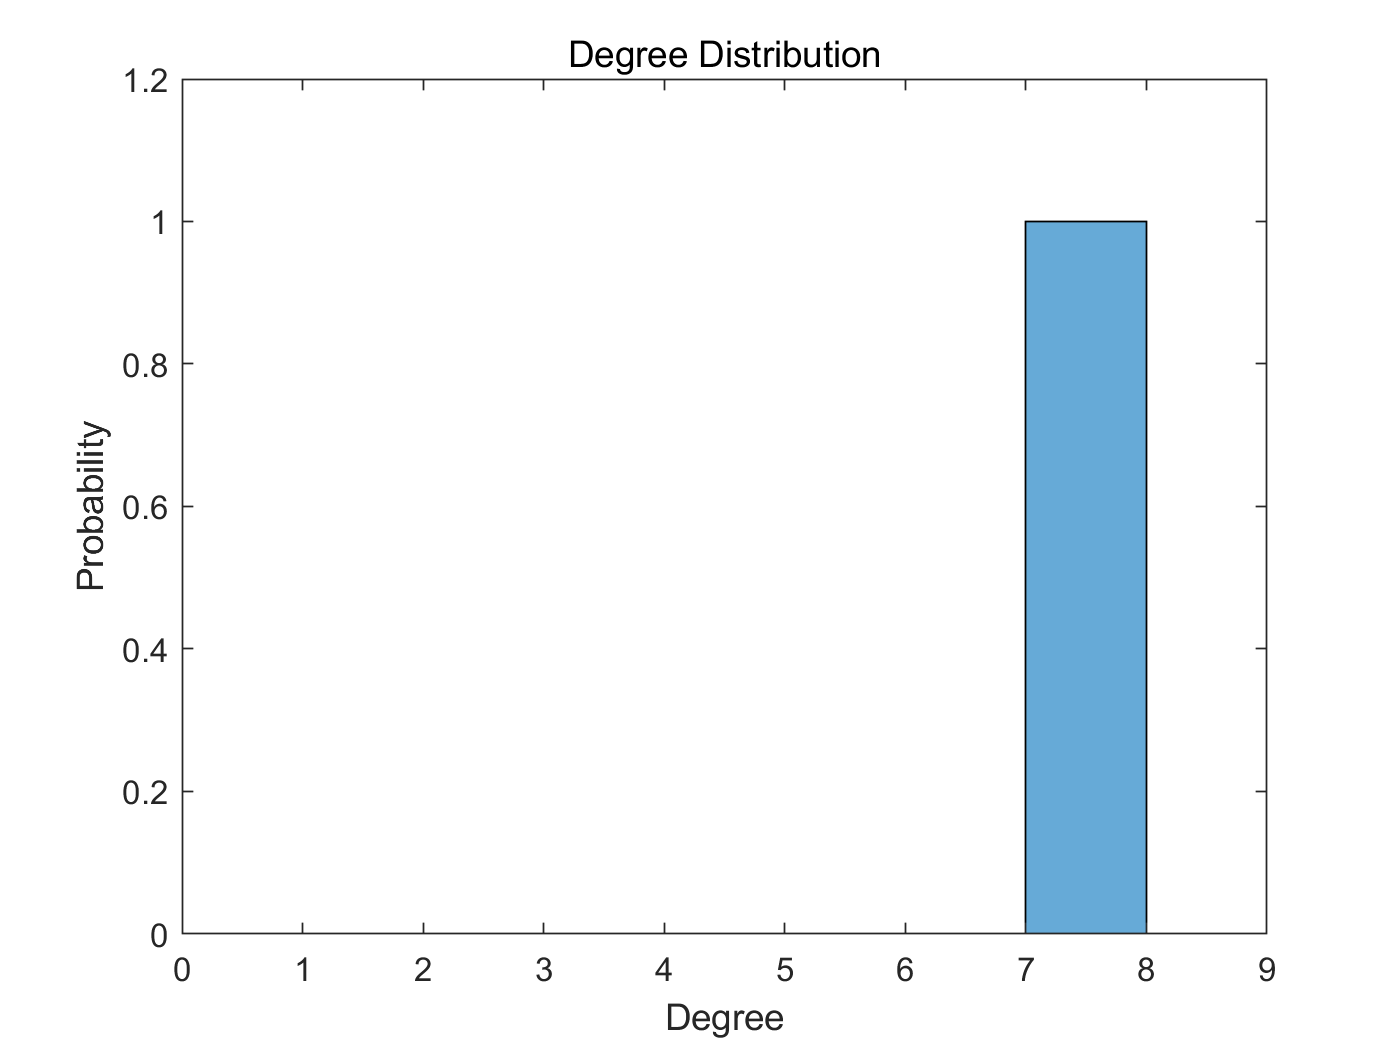

clear
clc

data=importdata("Employee_Relationships.txt");

G=graph();
for i=1:length(data.data)
    G=addedge(G,data.textdata(i,1), data.textdata(i,2), data.data(i));
end
deg=degree(G);
histogram(deg,[0:8],'Normalization','probability');
axis([0 9 0 1.2]);
xlabel("Degree");
ylabel("Probability");
title("Degree Distribution")

2.2 Implement the greedy algorithm we introduced in the class to generate a list of movies to display in the movie night, so that each employee could at least have one movie they like, and the total number of movies that needs to be displayed is also minimized.

clear
clc

data=importdata("Employee_Movie_Choices.txt");
data(1)=[];
data=split(data,sprintf('\t'));
M = containers.Map;
U={};
for i=1:length(data)
    key=cell2mat(data(i,2));
    val=cell2mat(data(i,1));
    if ~any(strcmp(U,val))
        U=[U,val];
    end
    if M.isKey(key)
        M(key)=[M(key),val];
    else
        M(key)={val};
    end
end

curr={};
movies={};
while (length(curr)<length(U) || M.isempty)
    maxCnt=0;
    maxKey="";
    for key=M.keys
        cnt=0;
        for val=M(cell2mat(key))
            if ~any(strcmp(curr,val))
                cnt=cnt+1;
            end
        end
        if cnt>maxCnt
            maxCnt=cnt;
            maxKey=key;
        end
    end
    movies=[movies,maxKey];
    curr=[curr,M(cell2mat(maxKey))];
    M.remove(maxKey);
end
disp(movies);

    {'Anaconda'}    {'The Shawshank Redemption'}    {'Forrest Gump'}



3. Suppose we have 6 nodes in the network which forms a directed graph with 9 edges. The connection relationship is given as source node set s = [1 1 2 2 3 3 3 4 5], and destination node set t = [2 5 3 4 4 5 6 1 1], where edge i is from s[i] to t[i].

3.1 Display the adjacency matrix M of this directed graph, where element Mij=1 if there is an edge from node i to node j.

clear
clc

s = [1 1 2 2 3 3 3 4 5];
t = [2 5 3 4 4 5 6 1 1];

G=digraph(s,t);
disp(full(G.adjacency));

     0     1     0     0     1     0
     0     0     1     1     0     0
     0     0     0     1     1     1
     1     0     0     0     0     0
     1     0     0     0     0     0
     0     0     0     0     0     0



3.2 Implement the pagerank algorithm we introduced in page49 of slide: 12-web_pagerank.pdf and display the pagerank score for each node. The random teleport probability β is set to be 0.85.

clear
clc

s = [1 1 2 2 3 3 3 4 5];
t = [2 5 3 4 4 5 6 1 1];

G=digraph(s,t);

rank=1/G.numnodes*ones(G.numnodes,1);
beta=0.85;
M=full(G.adjacency)';
[m,n]=size(M);
for c=[1:n]
    temp=1/sum(M(:,c));
    for r=[1:m]
        if M(r,c)==1
            M(r,c)=temp;
        end
    end
end

A=beta*M+(1-beta)*1/G.numnodes*ones(G.numnodes);
for c=[1:n]
    temp=sum(M(:,c));
    if temp==0
        for r=[1:m]
            A(r,c)=1/G.numnodes;
        end
    end
end

nextRank=rank;
rank=zeros(G.numnodes,1);
while nextRank~=rank
    rank=nextRank;
    nextRank=A*rank;
end

for i=[1:length(rank)]
    disp([num2str(i),sprintf('\t'),num2str(rank(i))]);
end

1	0.32102
2	0.17054
3	0.10659
4	0.13679
5	0.20074
6	0.064312
